syms Kd
syms Kp
syms c
syms s
syms v0
syms phi0

A = [0 0 -v0*sin(phi0) 0;
    0 0 v0*cos(phi0) 0;
    0 0 0 -Kd*c^2;
    0 0 0 -c];
B = [0;0;Kp+Kd*c;1];
C = [0 0 0 -Kd*c^2];
D = Kp+Kd*c;
K = (s*eye(4)-A)

$$K = \left(\begin{array}{cccc} s & 0 & v_{0}\,\sin\left(\varphi_{0}\right) & 0\\ 0 & s & -v_{0}\,\cos\left(\varphi_{0}\right) & 0\\ 0 & 0 & s & \mathrm{Kd}\,c^{2}\\ 0 & 0 & 0 & c+s \end{array}\right)$$

%P = det(K)
GP = simplify(C*inv(K)*B+D)

$$GP = \mathrm{Kp}+\mathrm{Kd}\,c-\frac{\mathrm{Kd}\,c^{2}}{c+s}$$

FT = simplify(GP/(1+GP))

$$FT = \frac{\mathrm{Kp}\,c+\mathrm{Kp}\,s+\mathrm{Kd}\,c\,s}{c+s+\mathrm{Kp}\,c+\mathrm{Kp}\,s+\mathrm{Kd}\,c\,s}$$

[~,P] = numden(simplify(FT))

$$P = c+s+\mathrm{Kp}\,c+\mathrm{Kp}\,s+\mathrm{Kd}\,c\,s$$

solve(P == 0,s)

$$ans = -\frac{c+\mathrm{Kp}\,c}{\mathrm{Kp}+\mathrm{Kd}\,c+1}$$

kp = 1;
c_ = 1;
kd = 1;

ft = tf([kp+kd*c_ kp*c_],[(1+kd*c_+kp) c_+kp*c_])

ft =
 
  2 s + 1
  -------
  3 s + 2
 
Continuous-time transfer function.



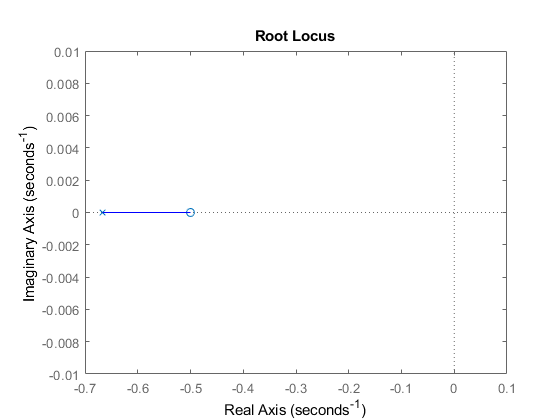


rlocus(ft)